**EJEMPLO 17**

Resolución de una ecuación algebraica mediante un perceptrón. Queremos aproximar la solución de la ecuación no lineal 

                                                                       
$$x^3 -x-1=0$$


Para ello vamos a utilizar un perceptrón con función de activación identidad, con una entrada de información externa $x=1$, un peso sináptico entrenable $w$ y sin sesgo, $b=0$.

Para el entrenamiento vamos a utilizar la función de pérdida 

                                                                     
$$L={\left(x^3 -x-1\right)}^2$$


y para la actualización del parámetro w el descenso del gradiente con una tasa de aprendizaje $\eta =0\ldotp 1$ y un entrenamiento de 200 épocas. 

**a)** Representa en una figura que represente la arquitectura de la red neuronal que se va a utilizar.

**b) **Representa en una figura que represente los elementos necesarios para el proceso de entrenamiento del perceptrón.

**c)** Llevar a cabo ‘a mano’ los tres primeros pasos del proceso de entrenamiento del perceptrón que hemos diseñado para aproximar la solución de la ecuación dada. Tomar un valor inicial del peso sináptico $w=0$.

                                
$$\begin{array}{l}
w_0 =0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;L\left(w_0 \right)=1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;w_1 =w_0 -\eta \frac{\partial L}{\partial w}\left(w_0 \right)=-0\ldotp 2\\
w_1 =-0\ldotp 2\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;L\left(w_1 \right)=0\ldotp 652864\;\;\Rightarrow \;w_2 =w_1 -\eta \frac{\partial L}{\partial w}\left(w_1 \right)=-0\ldotp 342208\\
w_2 =-0\ldotp 342208\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;L\left(w_2 \right)=0\ldotp 487018\;\Rightarrow \;w_3 =w_2 -\eta \frac{\partial L}{\partial w}\left(w_2 \right)=-0\ldotp 432747
\end{array}$$
 

**d)** Implementar el proceso de entrenamiento en un programa MATLAB, verificando que el resultado de las 3 primeras épocas de entrenamiento coincide con el calculado en el apartado anterior.

format long
% Parámetros de entrada
x_test=1; % Entrada única de información
nu=0.1;   % Tasa de entrenamiento
w0=0;     % Peso inicial 

for i=1:4 
    w_actual=w0;
    L_perdida=(w_actual^3-w_actual-1)^2;
    perdidas(i)=L_perdida;
    w0=w_actual-nu*(2*(w_actual^3-w_actual-1)*(3*w_actual^2-1));
    fprintf('Época %d :  w = %.6f   L = %.6f\n',i-1,w_actual,L_perdida);
end

Época 0 :  w = 0.000000   L = 1.000000
Época 1 :  w = -0.200000   L = 0.652864
Época 2 :  w = -0.342208   L = 0.487018
Época 3 :  w = -0.432747   L = 0.420285


**e)** Elevar el número de épocas del entrenamiento para verificar cual es la precisión máxima que es posible obtener con esta estructura y esta tasa de entrenamiento. Para ello llevar a cabo una gráfica de la función de pérdida L en función de las épocas de entrenamiento 𝑛. Representar 𝑛 en abscisas y L en ordenadas. ¿Se observa un comportamiento de convergencia ‘clásico’ o se observa un ‘comportamiento oscilante’? ¿Es correcta la solución obtenida?

format long
% Parámetros de entrada
x_test=1; % Entrada única de información
nu=0.1;   % Tasa de entrenamiento
w0=0;     % Peso inicial 

for i=1:200 
    w_actual=w0;
    L_perdida=(w_actual^3-w_actual-1)^2;
    perdidas(i)=L_perdida;
    w0=w_actual-nu*(2*(w_actual^3-w_actual-1)*(3*w_actual^2-1));
    fprintf('Época %d :  w = %.6f   L = %.6f\n',i-1,w_actual,L_perdida);
end

Época 0 :  w = 0.000000   L = 1.000000
Época 1 :  w = -0.200000   L = 0.652864
Época 2 :  w = -0.342208   L = 0.487018
Época 3 :  w = -0.432747   L = 0.420285
Época 4 :  w = -0.489562   L = 0.394097
Época 5 :  w = -0.524841   L = 0.384066
Época 6 :  w = -0.546361   L = 0.380360
Época 7 :  w = -0.559247   L = 0.379039
Época 8 :  w = -0.566848   L = 0.378581
Época 9 :  w = -0.571284   L = 0.378426
Época 10 :  w = -0.573856   L = 0.378374
Época 11 :  w = -0.575341   L = 0.378356
Época 12 :  w = -0.576196   L = 0.378351
Época 13 :  w = -0.576687   L = 0.378349
Época 14 :  w = -0.576970   L = 0.378348
Época 15 :  w = -0.577132   L = 0.378348
Época 16 :  w = -0.577225   L = 0.378348
Época 17 :  w = -0.577278   L = 0.378348
Época 18 :  w = -0.577309   L = 0.378348
Época 19 :  w = -0.577327   L = 0.378348
Época 20 :  w = -0.577337   L = 0.378348
Época 21 :  w = -0.577342   L = 0.378348
Época 22 :  w = -0.577346   L = 0.378348
Época 23 :  w = -0.577348   L = 0.378348
Época 24 :  w = -0.577349  

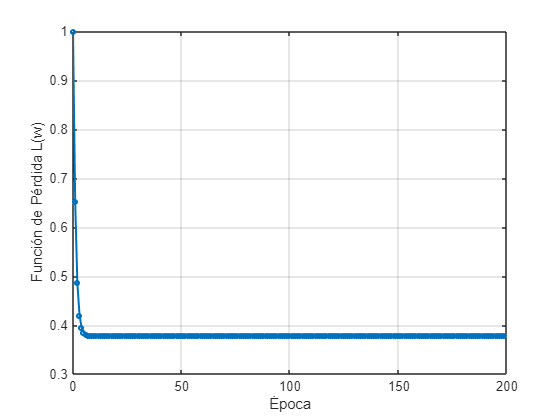

figure;
plot(0:199,perdidas,'-o','MarkerSize', 3,'LineWidth',1.5);
grid on;
xlabel('Época');
ylabel('Función de Pérdida L(w)');

**f)** Proponer alguna solución para mejorar la precisión con la que podemos mejorar el resultado sin alterar la arquitectura esencial que hemos utilizado en los apartados anteriores.

Para mejorar la precisión, se nos ocurren 3 posibles opciones, modificar $\eta ,w$ o la propia función de pérdida. Vamos a probar cada opción:

%--TASA DE ENTRENAMIENTO--
format long
% Parámetros de entrada
x_test=1; % Entrada única de información
nu=0.01;   % Tasa de entrenamiento MODIFICADA
w0=0;     % Peso inicial 

for i=1:200 
    w_actual=w0;
    L_perdida=(w_actual^3-w_actual-1)^2;
    perdidas(i)=L_perdida;
    w0=w_actual-nu*(2*(w_actual^3-w_actual-1)*(3*w_actual^2-1));
    fprintf('Época %d :  w = %.6f   L = %.6f\n',i-1,w_actual,L_perdida);
end

Época 0 :  w = 0.000000   L = 1.000000
Época 1 :  w = -0.020000   L = 0.960416
Época 2 :  w = -0.039577   L = 0.922532
Época 3 :  w = -0.058696   L = 0.886434
Época 4 :  w = -0.077332   L = 0.852171
Época 5 :  w = -0.095463   L = 0.819762
Época 6 :  w = -0.113076   L = 0.789201
Época 7 :  w = -0.130162   L = 0.760460
Época 8 :  w = -0.146716   L = 0.733493
Época 9 :  w = -0.162739   L = 0.708242
Época 10 :  w = -0.178233   L = 0.684638
Época 11 :  w = -0.193205   L = 0.662608
Época 12 :  w = -0.207662   L = 0.642071
Época 13 :  w = -0.221614   L = 0.622947
Época 14 :  w = -0.235074   L = 0.605154
Época 15 :  w = -0.248053   L = 0.588611
Época 16 :  w = -0.260565   L = 0.573240
Época 17 :  w = -0.272623   L = 0.558964
Época 18 :  w = -0.284242   L = 0.545712
Época 19 :  w = -0.295435   L = 0.533413
Época 20 :  w = -0.306217   L = 0.522001
Época 21 :  w = -0.316602   L = 0.511415
Época 22 :  w = -0.326604   L = 0.501597
Época 23 :  w = -0.336236   L = 0.492491
Época 24 :  w = -0.345511  

Esta opción no sirve ya que la función de pérdida sigue sin converger a 0, probamos con modificar la tasa y el peso:

%--PESO Y TASA DE ENTRENAMIENTO--
format long
% Parámetros de entrada
x_test=1; % Entrada única de información
nu=0.01;   % Tasa de entrenamiento
w0=1;     % Peso inicial MODIFICADO

for i=1:100 
    w_actual=w0;
    L_perdida=(w_actual^3-w_actual-1)^2;
    perdidas(i)=L_perdida;
    w0=w_actual-nu*(2*(w_actual^3-w_actual-1)*(3*w_actual^2-1));
    fprintf('Época %d :  w = %.6f   L = %.6f\n',i-1,w_actual,L_perdida);
end

Época 0 :  w = 1.000000   L = 1.000000
Época 1 :  w = 1.040000   L = 0.837474
Época 2 :  w = 1.081086   L = 0.668421
Época 3 :  w = 1.122066   L = 0.503174
Época 4 :  w = 1.161465   L = 0.353606
Época 5 :  w = 1.197703   L = 0.230023
Época 6 :  w = 1.229390   L = 0.137856
Época 7 :  w = 1.255635   L = 0.076164
Época 8 :  w = 1.276222   L = 0.039040
Época 9 :  w = 1.291579   L = 0.018768
Época 10 :  w = 1.302551   L = 0.008573
Época 11 :  w = 1.310125   L = 0.003769
Época 12 :  w = 1.315220   L = 0.001612
Época 13 :  w = 1.318584   L = 0.000677
Época 14 :  w = 1.320777   L = 0.000280
Época 15 :  w = 1.322195   L = 0.000115
Época 16 :  w = 1.323106   L = 0.000047
Época 17 :  w = 1.323690   L = 0.000019
Época 18 :  w = 1.324063   L = 0.000008
Época 19 :  w = 1.324301   L = 0.000003
Época 20 :  w = 1.324452   L = 0.000001
Época 21 :  w = 1.324549   L = 0.000001
Época 22 :  w = 1.324610   L = 0.000000
Época 23 :  w = 1.324649   L = 0.000000
Época 24 :  w = 1.324674   L = 0.000000
Época 25 :

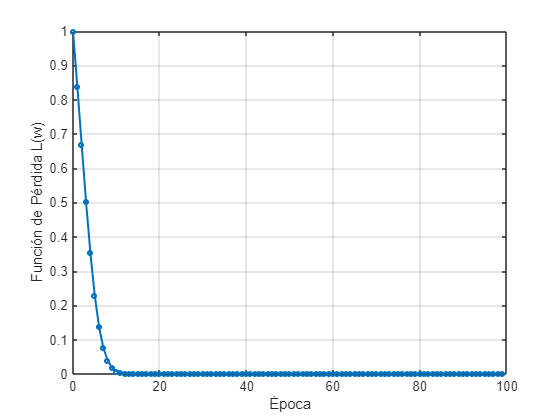

figure;
plot(0:99,perdidas_new,'-o','MarkerSize', 3,'LineWidth',1.5);
grid on;
xlabel('Época');
ylabel('Función de Pérdida L(w)');